# Pellet Smoker: Scenario

## Play Space

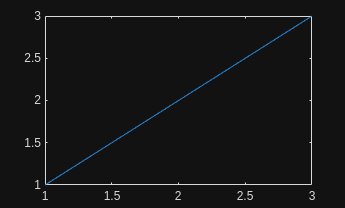



plot([1 2 3])


% differential equation
a_dot = @(t,a) myfunct(a)

a_dot = function_handle with value:
    @(t,a)myfunct(a)


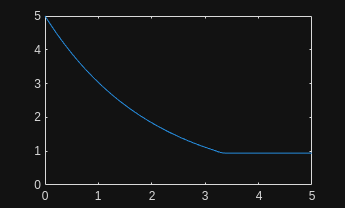

  Line with properties:

              Color: [0.1490 0.5490 0.8660]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.1005 0.2010 0.3014 0.4019 0.5269 0.6519 0.7769 0.9019 1.0269 1.1519 1.2769 1.4019 1.5269 1.6519 1.7769 1.9019 2.0269 2.1519 2.2769 2.4019 2.5269 2.6519 2.7769 2.9019 2.9715 3.0410 3.1106 3.1802 3.2498 3.3193 … ] (1×49 double)
              YData: [5 4.7550 4.5220 4.3005 4.0898 3.8420 3.6092 3.3905 3.1851 2.9921 2.8108 2.6405 2.4806 2.3303 2.1891 2.0565 1.9319 1.8148 1.7049 1.6016 1.5045 1.4134 1.3278 1.2473 1.1717 1.1317 1.0930 1.0556 1.0195 0.9801 0.9502 … ] (1×49 double)

  Use GET to show all properties




[t,result] = ode45(a_dot, [0 5], 5);
disp(plot(t,result))


function pres = myfunct(a)
    if a < 1
        pres = 0;
    else
        pres = -0.5*a;
    end
end

## what

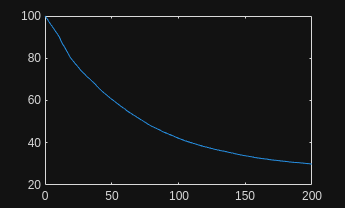


%t = nonlinear_model([1;2;3],[1;2])


u = [0.1; 0.5];

mycontrol = @(t,x) nonlinear_model(t,x,u);

[t, result] = ode45(mycontrol, [0 200], [100 100 100]);

plot(t, result(:,2)) % 26.0336

## setting up A and B linearized

scr_symbols

scr_syms: created symbols
  - syms C_f C_c k_f k_fa k_ca gamma T_amb
  - syms x_1 x_2 x_3 u_p u_f


scr_p2_2

scr_nonlinear_model: created nonlinear model
  - x_dot_nonlinear: anonymous function of inputs x and u
  - T_f_dot_nonlinear: anonymous function x_dot(1)
  - T_c_dot_nonlinear: anonymous function x_dot(2)
  - m_p_dot_nonlinear: anonymous function x_dot(3)


scr_p2_4_3

ans = '\left(\begin{array}{cc} \frac{\gamma \,u_{f}}{C_{f}} & \frac{\gamma \,u_{p}}{C_{f}}\\ 0 & 0\\ -1 & 0 \end{array}\right)'

mat2str(double(subs(p2_4_3.A,[param_symbols point_symbols], [param_values, [25 25 100 0 0.5]])))

ans = '[-0.34 0.3 0;0.06 -0.07 0;0 0 0]'

## First test

% nonlinear_model(t, x, u)
% static_observer(y,x_hat,u)
% static_feedback_1(x_hat)

mycontrol = @(t,xb) [nonlinear_model(t,xb(1:3),static_feedback_1(xb(4:6)));static_observer(xb(2), xb(4:6), static_feedback_1(xb(4:6)))];

[t, result] = ode45(mycontrol, [0 200], [30 30 100 30 30 100]);

Error using static_feedback_1 (line 3)
Invalid argument list. Function requires 2 more input(s).

Error in LIVE_SCRIPT>@(t,xb)[nonlinear_model(t,xb(1:3),static_feedback_1(xb(4:6)));static_observer(xb(2),xb(4:6),static_feedback_1(xb(4:6)))] (line 37)
mycontrol = @(t,xb) [nonlinear_model(t,xb(1:3),static_feedback_1(xb(4:6)));static_observer(xb(2), xb(4:6), static_feedback_1(xb(4:6)))];
^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^
Error in odearguments (line 93)
f0 = ode(t0,y0,args{:});
^^^^^^^^^^^^^^^^^^^^^^^^
Error in ode45 (line 104)
    odearguments(odeIsFuncHandle,odeTreatAsMFile, solver_name, ode, tspan, y0, options, varargin);
    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^


plot(t, result(:,1)) % 26.0336
title("T_f")
figure;
plot(t, result(:,2)) % 26.0336
title("T_c")
figure;
plot(t, result(:,4)) % 26.0336
title("T_fhat")
figure;
plot(t, result(:,5)) % 26.0336
title("T_chat")
figure;
u = [8.4 326;1.69 65]*([118;5.59]*(result(:,2)'-26.0336));
%u = [max(0,u_unsat(1)); max(0,min(1,u_unsat(2)))];
plot(t, u(1,:)) % 26.0336
title("u_p")
figure;
plot(t, u(2,:)) % 26.0336
title("u_f")
figure;

## another

scr_symbols
p2_4_3.A = jacobian(x_dot_nonlinear([x_1;x_2;x_3], [u_p; u_f]),[x_1;x_2;x_3]);
p2_4_3.B = jacobian(x_dot_nonlinear([x_1;x_2;x_3], [u_p; u_f]),[u_p;u_f]);

## 2.7.1 Set Particulars

p.C_f = 500;
p.k_f = 150;
p.k_ca = 25;
p.C_c = 2500;
p.k_fa = 20;
p.gamma = 1000;
p.T_amb = 25;

## 2.7.2 Open-Loop Linear vs Nonlinear

lin = linearize(p, [0.4, 0.6]);

u = @(t) (t<100)*[4;1];

control = @(t,x) A*x+B*u(t)


## Closed-Loop Feedback, Naive Observer Design

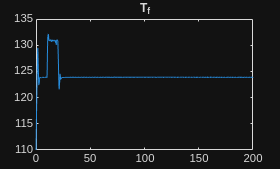

lin = linearize(p, [0.4, 0.6]);
t_min = 0;
t_max = 200;

setpoint = @(t) [(t>=0)*110; (t>=0)*110; 0];
door_open = @(t) (t>=10)&&(t<20);

mycontrol = @(t,xb) [nonlinear_model(door_open(t),xb(1:3),static_feedback_1(xb(4:6),setpoint(t),lin));static_observer(xb(2), xb(4:6), static_feedback_1(xb(4:6),setpoint(t),lin),lin)];

[t, result] = ode45(mycontrol, [t_min t_max], [110 110 1000 110 110 1000]);


plot(t, result(:,1)) % 26.0336
title("T_f")

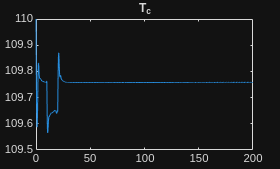

figure;
plot(t, result(:,2)) % 26.0336
title("T_c")

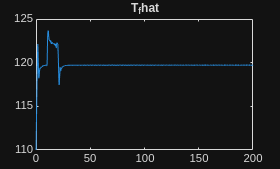

figure;
plot(t, result(:,4)) % 26.0336
title("T_fhat")

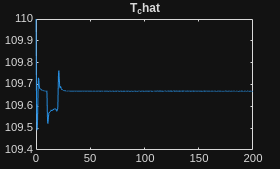

figure;
plot(t, result(:,5)) % 26.0336
title("T_chat")

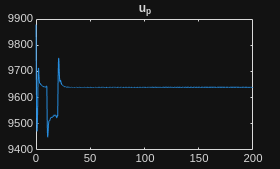

figure;
u = [4.57 155; 3.04 103.385]*([25.89;5.61]*(result(:,2)'-100));
%u = [max(0,u_unsat(1)); max(0,min(1,u_unsat(2)))];
plot(t, u(1,:)) % 26.0336
title("u_p")

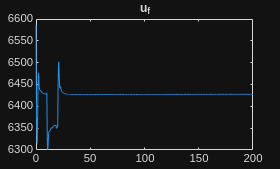

figure;
plot(t, u(2,:)) % 26.0336
title("u_f")

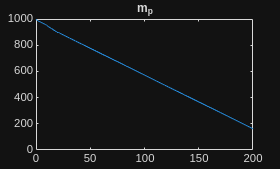

figure;
plot(t, result(:,3)) % 26.0336
title("m_p")

figure;


% After capturing these figures (don't set any k values to zero explicitly)
% you notice that overshoot is an issue. You could reduce this by lessening
% your eigenvalue magnitudes, but notice first that we can make some
% cost-free optimizations first by improving our state observer. We know
% that we have perfect observation of T_c but T_f is not all that--there is
% delay in estimating T_f that costs us like 20 degrees of uncontrolled
% overshoot.

% First, can we just try and get rid of the T_f gain? After all, only T_c
% matters. However, if you do that (which is very easy) you will see that
% T_f oscillates a bunch, and T_c gets fuzzier. We don't want that.

% Instead, we can be clever with our state observer. I call my choice the
% dynamic state observer

## Linearization Test

A2 = lin.A(1:2,1:2)
B2 = lin.B(1:2,1:2)
lin.A
lin.B

k = [place(A2,B2,[-3.8+0.2i; -3.8-0.2i]),[0;0]]
L = [place(A2, [0;1], [-3.1 -2.9])'; 0] % arbitrary poles


## Feedback Saturation Test

% test the saturation
p.k_fa
static_feedback_1([1000;110;0],[1000;0;0],linearize(p, [0.4, 0.6]))

## Matlab test


system_differential(nonlinear_model,1,[1;1;1],[0;0])

Error using nonlinear_model (line 1)
Invalid argument list. Function requires 3 more input(s).

## U plotting

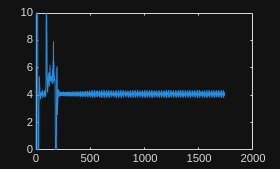

% take in the linear system
A2 = lin.A(1:2,1:2);
B2 = lin.B(1:2,1:2);

k = [place(A2,B2,[-3.8+0.2i; -3.8-0.2i]),[0;0]];

u_unsat = -k*((result(:,4:6)-setpoint(0)')');
u = [max(0,min(10,u_unsat(1,:))); max(0,min(1,u_unsat(2,:)))];


figure;
plot(u(1,:))

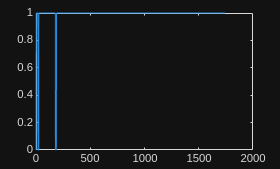

figure;
plot(u(2,:))

## test nonlinear system

scr_symbols

scr_syms: created symbols
  - syms C_f C_c k_f k_fa k_ca gamma T_amb
  - syms x_1 x_2 x_3 u_p u_f


x_dot_nonlinear = [
        1/C_f * (  -k_f*(x_1-x_2) -k_fa*(x_1-T_amb) +gamma*u_p*u_f  );
        1/C_c * (   k_f*(x_1-x_2) -k_ca*(x_2-T_amb)  );
        -u_p;
    ]

$$x\_dot\_nonlinear = \left(\begin{array}{c} \frac{k_{\mathrm{fa}}\,\left(T_{\mathrm{amb}}-x_{1}\right)-k_{f}\,\left(x_{1}-x_{2}\right)+\gamma \,u_{f}\,u_{p}}{C_{f}}\\ \frac{k_{\mathrm{ca}}\,\left(T_{\mathrm{amb}}-x_{2}\right)+k_{f}\,\left(x_{1}-x_{2}\right)}{C_{c}}\\ -u_{p} \end{array}\right)$$